# Simulating growth of a diamond film by CVD

This example computes the growth rate of a diamond film according to a simplified version of a particular published growth mechanism (see file ``diamond.yaml`` for details). Only the surface coverage equations are solved here; the gas composition is fixed. (For an example of coupled gas-phase and surface, see :doc:`catcomb.m [catcomb](http://catcomb)`).

Atomic hydrogen plays an important role in diamond CVD, and this example computes the growth rate and surface coverages as a function of [H] at the surface for fixed temperature and [CH3].

## Initialization

clear all
close all
ctLoad

Cantera 3.2.0a1 is ready for use.


## Operation Parameters

t = 1200.0; % surface temperature
p = 20.0 * OneAtm / 760.0; % pressure

## Create the gas object

The gas phase will be taken from the definition of phase 'gas' in input file 'diamond.yaml'.

gas = Solution('diamond.yaml', 'gas');
gas.TP = {t, p}


  gas:

       temperature   1200 K
          pressure   2666.4 Pa
           density   0.00057641 kg/m^3
  mean mol. weight   2.1568 kg/kmol
   phase of matter   gas

                          1 kg             1 kmol     
                     ---------------   ---------------
          enthalpy        1.2418e+07        2.6783e+07  J
   internal energy         7.792e+06        1.6806e+07  J
           entropy             94362        2.0352e+05  J/K
    Gibbs function       -1.0082e+08       -2.1744e+08  J
 heat capacity c_p             14600             31490  J/K
 heat capacity c_v             10745             23176  J/K

                      mass frac. Y      mole frac. X     chem. pot. / RT
                     ---------------   ---------------   ---------------
                 H        0.00093452         0.0019996           -3.4029
                H2            0.9233            0.9878           -21.627
               CH3         0.0013939        0.00019996           -24.284
 

x = gas.X;
ih = gas.speciesIndex('H');
xh0 = x(ih);

## Create the bulk diamond object

The bulk phase will be taken from the definition of phase 'diamond' in input file 'diamond.yaml'.

dbulk = Solution('diamond.yaml', 'diamond')


  diamond:

       temperature   298.15 K
          pressure   1.0132e+05 Pa
           density   3520 kg/m^3
  mean mol. weight   12.011 kg/kmol
   phase of matter   unspecified

                          1 kg             1 kmol     
                     ---------------   ---------------
          enthalpy                 0                 0  J
   internal energy           -28.786           -345.74  J
           entropy                 0                 0  J/K
    Gibbs function                 0                 0  J
 heat capacity c_p                 0                 0  J/K
 heat capacity c_v                 0                 0  J/K

                      mass frac. Y      mole frac. X     chem. pot. / RT
                     ---------------   ---------------   ---------------
              C(d)                 1                 1                 0



mw = dbulk.molecularWeights;

## Create the interface object

This object will be used to evaluate all surface chemical production rates. It will be created from the interface definition 'diamond_100' in input file 'diamond.yaml'.

surf_phase = Interface('diamond.yaml', 'diamond_100', gas, dbulk)


  diamond_100:

       temperature   1200 K
          pressure   1.0132e+05 Pa
           density   5.7456e-08 kg/m^3
  mean mol. weight   1.9152 kg/kmol
   phase of matter   unspecified

                          1 kg             1 kmol     
                     ---------------   ---------------
          enthalpy        3.3709e+07        6.4559e+07  J
   internal energy        3.3709e+07        6.4559e+07  J
           entropy             46961             89939  J/K
    Gibbs function       -2.2644e+07       -4.3368e+07  J
 heat capacity c_p                 0                 0  J/K
 heat capacity c_v                 0                 0  J/K

                      mass frac. Y      mole frac. X     chem. pot. / RT
                     ---------------   ---------------   ---------------
              c6HH           0.94737               0.9           -5.8924
              c6H*          0.052632               0.1             9.565
     [   +6 minor]                 0                 0

## Advance Coverages

iC = surf_phase.kineticsSpeciesIndex('C(d)');

xx = [];
rr = [];
cov = [];

for i = 1:20
    x(ih) = x(ih) / 1.4;
    gas.TPX = {t, p, x};
    surf_phase.advanceCoverages(10.0);
    r = surf_phase.netProdRates;
    carbon_dot = r(iC);
    mdot = mw * carbon_dot;
    rate = mdot / dbulk.D;
    xx = [xx; x(ih)];
    rr = [rr; rate * 1.0e6 * 3600.0];
    cov = [cov; surf_phase.coverages];
end

## Make Plots

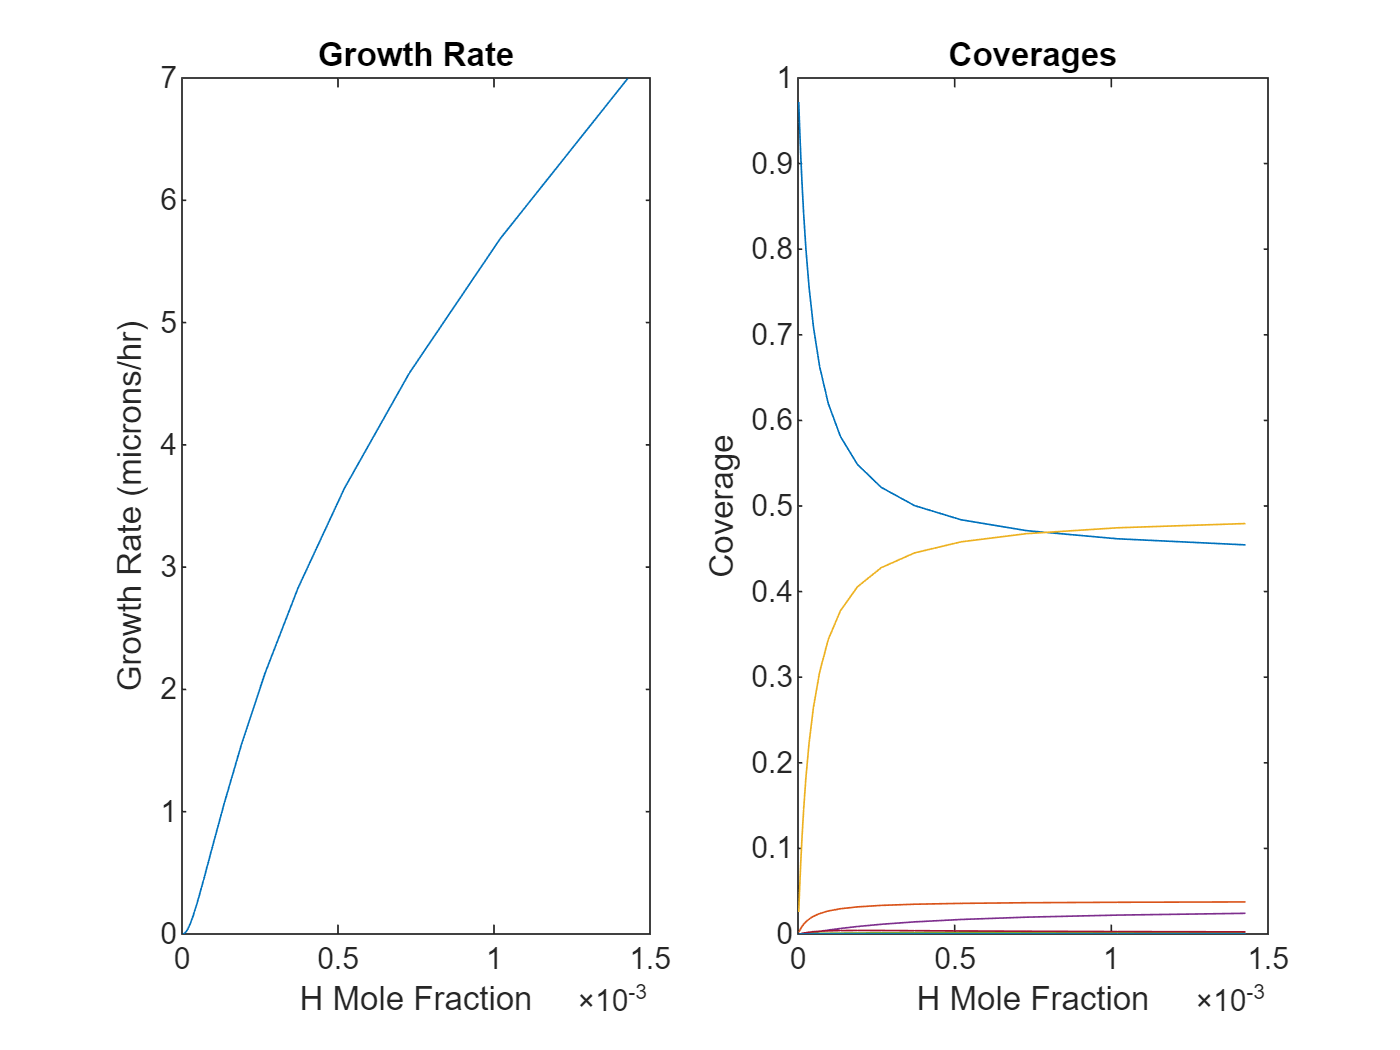

clf;

subplot(1, 2, 1);
plot(xx, rr);
xlabel('H Mole Fraction');
ylabel('Growth Rate (microns/hr)');
title('Growth Rate');

subplot(1, 2, 2);
plot(xx, cov);
xlabel('H Mole Fraction');
ylabel('Coverage');
title('Coverages');